# EEE3548 Exercise #5 Phase Contrast Microscopy

## [23.06.02] [ImHyeonJeong]

#### Q1. Define an object with complex transmittance. Suppose that 2 objects with specific shape(circle, rectangle...) are in the water, one has only transmittance of 0.8 and the other has only phase(thickness of 500 nm, refractive index(RI) of the object is 1.38). Plot the amplitude and phase seperately of the objects. (Set the pixel size is 100 nm, Number of the pixels is 256, wavelength as 500 nm, refractive index of media is 1.33).

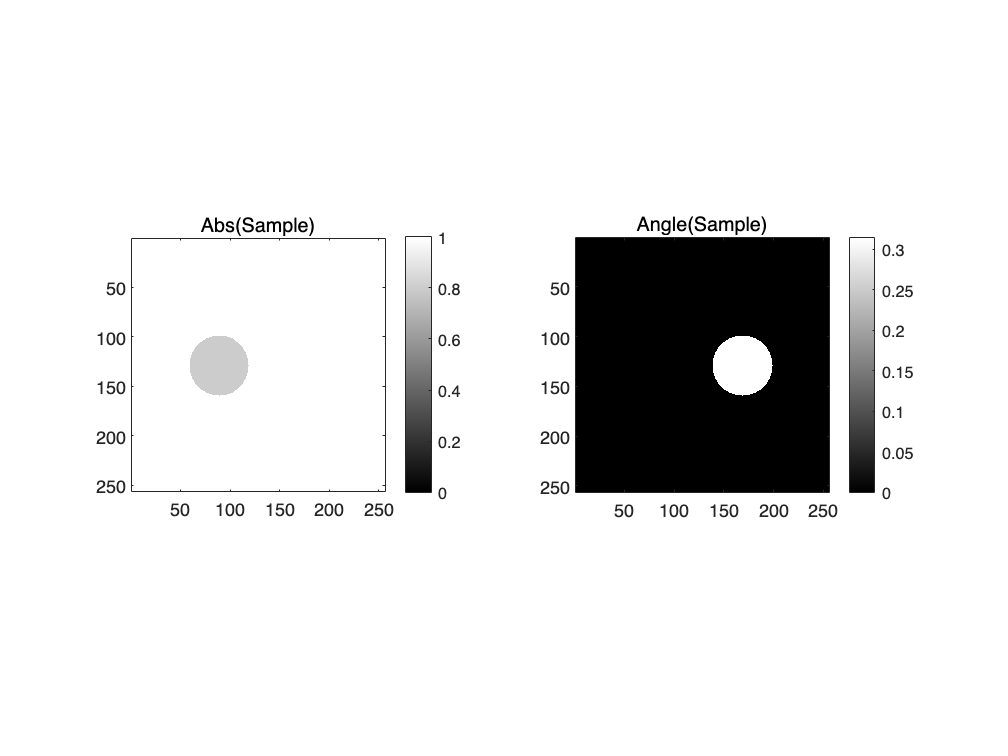

clc;clear;

% Setting xy-space
psize = 100e-9;
x = -128*psize : psize : 127*psize; 
y = -128*psize : psize : 127*psize; 
[X, Y] = meshgrid(x, y);
R = 3e-6;
 
% Amplitude object (Left)
obj_a = ones(256);
obj_a(((X+40*psize).^2 + Y.^2) < R.^2) = 0.8;

% Setting parameters for phase object
lamda = 500e-9; % wavelength
k = 2*pi/lamda;
n = 1.38; n_water = 1.33;

% Phase object (Right)
obj_p = zeros(256);
obj_p(((X-40*psize).^2 + Y.^2) < R.^2) = 1;

% Total objects
objs = obj_a .* exp(1j*k*(n-n_water)*lamda*obj_p);

% Plot
figure;
subplot(121); imagesc(abs(objs)); colormap gray; clim([0 max(objs(:))]); axis image; title('Abs(Sample)'); colorbar
subplot(122); imagesc(angle(objs)); colormap gray; axis image; title('Angle(Sample)'); colorbar

**Result** : Sample에 대해 Abs를 취했을 때에는 Amplitude object만 관찰되며 Phase object는 보이지 않았다. 반대로 Angle을 취했을 때는 Phase object만 관찰되며 Amplitude object는 보이지 않았다.

#### Q2. Define an ideal optical transfer function(OTF) with NA=0.5. (Use cut-off frequency $k_c =\frac{\textrm{NA}}{\lambda }$). Also, Plot the OTF.

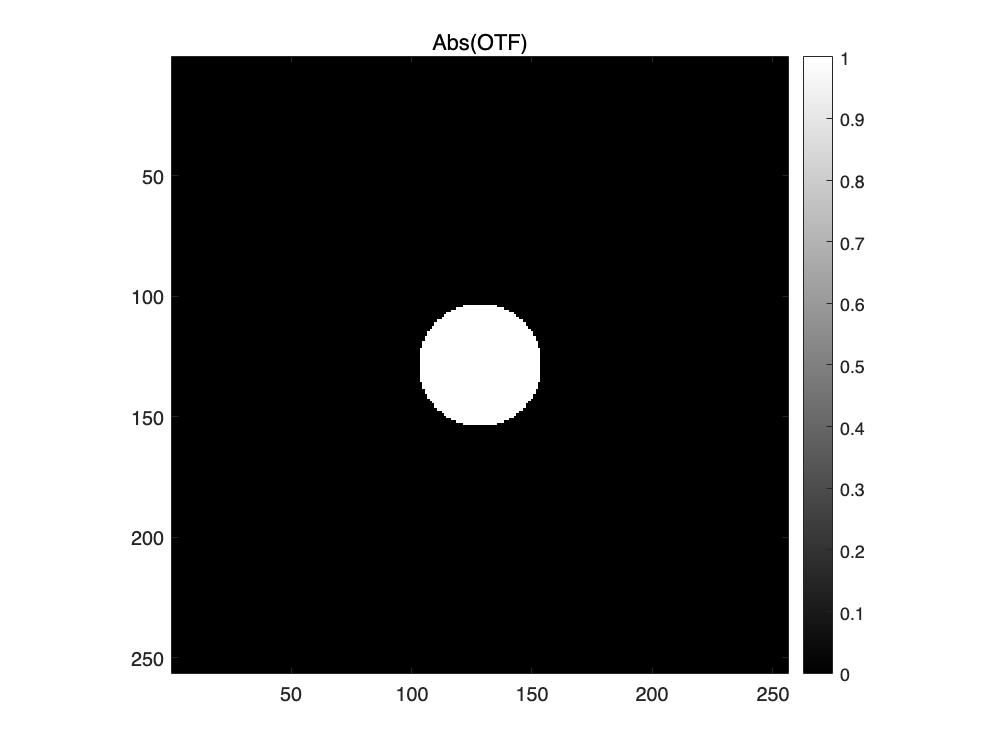

% Setting k-space
N = 256; psize = 100e-9; 
kx = linspace(-1/2, 1/2, N)/psize; 
ky = linspace(-1/2, 1/2, N)/psize;
[KX, KY] = meshgrid(kx, ky);

% Setting parameters
NA = 0.5; lamda = 500e-9;
kc = NA/lamda;

% Ideal OTF
OTF = (KX.^2+KY.^2) < kc.^2;

% Plot
figure; imagesc(abs(OTF)); colormap gray; axis image; title('Abs(OTF)'); colorbar

#### Q3. Image the object from Q1. Plot the intensity of the result image.

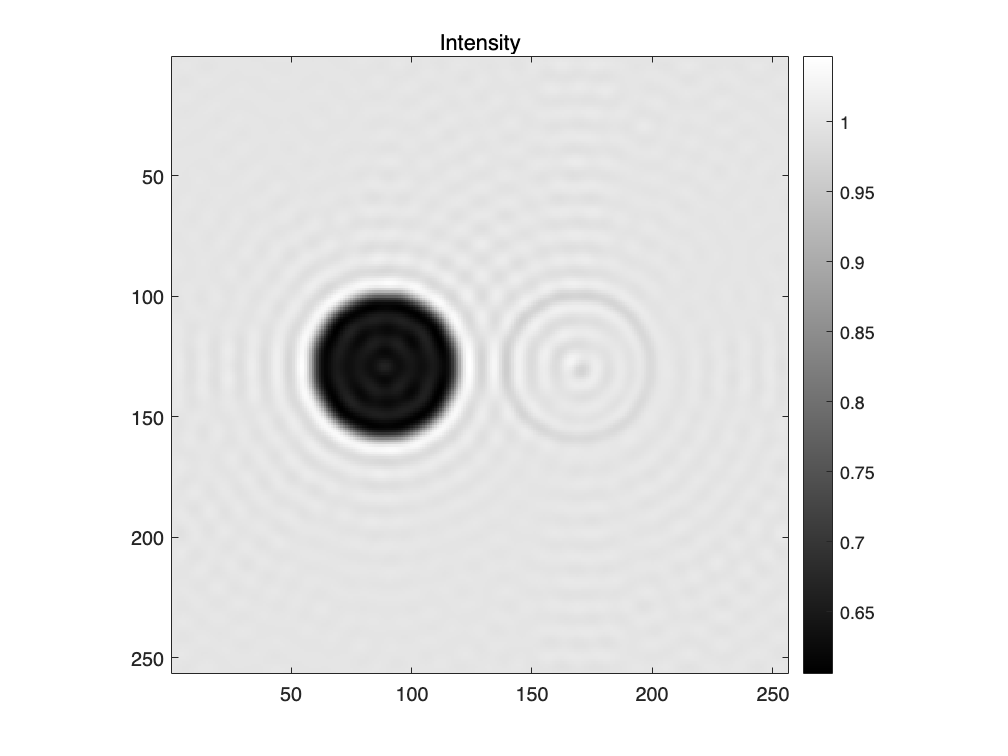

I = ifft2(ifftshift(OTF.*fftshift(fft2(objs))));

figure; imagesc(abs(I).^2); colormap gray; axis image; title('Intensity'); colorbar

**Result **: Amplitude object는 잘 보이지만, Phase object는 잘 안보임

#### Q4. Simulate the phase contrast microscopy image with custom OTF. Set the amplitue with a concentric circle, outer NA=0.5 and inner NA=0.01, at which the outer area has amplitude of 1 and the inner has 0.2. Also the phase has circle shape with NA=0.01, with phase $\pi/2$ . Plot the amplitude and phase of the OTF, and plot the intensity image of the sample. Compare the result with Q3.

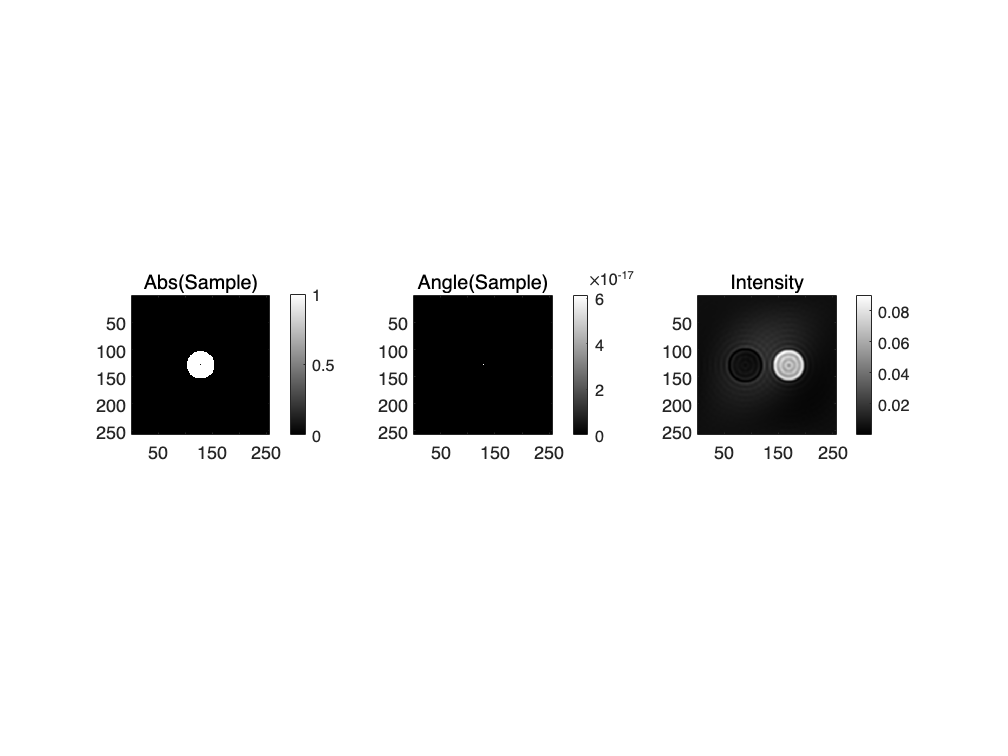

% Setting parameters
NA_o = 0.5; NA_i = 0.02; lamda = 500e-9;
kc_o = NA_o/lamda; kc_i = NA_i/lamda;

% Amplitude
Amp = zeros(256);
Amp(((KX.^2+KY.^2) < kc_o.^2) & ((KX.^2+KY.^2) > kc_i.^2) ) = 1;
Amp((KX.^2+KY.^2) < kc_i.^2) = 0.2;

% Phase
Phase = ((KX.^2+KY.^2) < kc_i.^2) .* exp(1j*(pi/2));

% Custome OTF for pcm
OTF_pcm = abs(Amp) .* exp(1j*angle(Phase));
% OTF_pcm = Amp .* exp(1j*Phase);

% Intensity
I_pcm = ifft2(ifftshift(OTF_pcm.*fftshift(fft2(objs))));

% Plot
figure;
subplot(131); imagesc(abs(OTF_pcm)); colormap gray; axis image; title('Abs(Sample)'); colorbar
subplot(132); imagesc(angle(OTF_pcm)); colormap gray; axis image; title('Angle(Sample)'); colorbar
subplot(133); imagesc(abs(I_pcm).^2); colormap gray; axis image; title('Intensity'); colorbar

**Result **: Custom OTF를 이용하여 Phase contrast microscopy를 적용했더니 Phase object가 잘 보였다.

Low spatial frequency 성분과 high special frequency 성분에 phase shift를 줄 수 있는 어떤 플레이트를 현미경에 넣었더니 일종의 bandpass filtering 효과가 발생한 것으로 해석할 수 있다. 